# 传感器作业1-6

x=[0,0.5,1.0,1.5,2.0,2.5];
y1f=[0.0020,0.2015,0.4005,0.6000,0.7995,1.0000];
y1b=[0.0030,0.2020,0.4020,0.6010,0.8005,1.0000];
y2f=[0.0025,0.2020,0.4010,0.6000,0.7995,0.9995];
y2b=[0.0035,0.2030,0.4020,0.6015,0.8005,0.9995];
y3f=[0.0035,0.2020,0.4010,0.6000,0.7995,0.9990];
y3b=[0.0040,0.2030,0.4020,0.6010,0.8005,0.9990];

求出平均值：

y=mean([y1f;y1b;y2f;y2b;y3f;y3b]);

使用“端点直线法”

k=(y(end)-y(1))/(x(end)-x(1));
b=y(1)-k*x(1);
y_1=k*x+b;

使用最小二乘法

coefficient=polyfit(x,y,1) ;
k=coefficient(1);b=coefficient(2);
y_2=k*x+b;

数据

name={'压力';'原始数据';'端点直线法';'最小二乘法'};
data=table([x;y;y_1;y_2]);
data.Properties.RowNames = name

data = 4×1 table
                     Var1    
                 ____________

    压力         [1x6 double]
    原始数据      [1x6 double]
    端点直线法    [1x6 double]
    最小二乘法    [1x6 double]


绘图

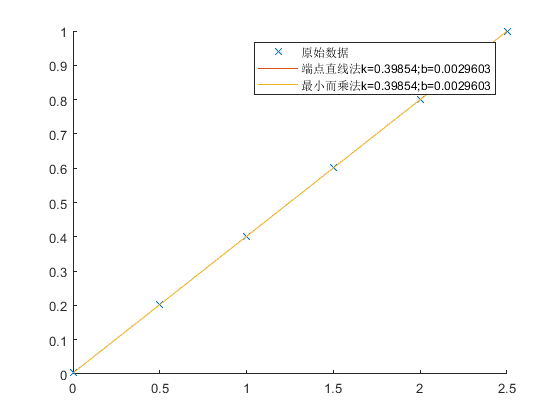

hold on 
plot(x,y,'x')
plot(x,y_1)
plot(x,y_2);
legend("原始数据",strcat('端点直线法k=',num2str(k),';b=',num2str(b)),strcat('最小而乘法k=',num2str(k),';b=',num2str(b)))
hold off